clear;
close all;
clc;
initime = clock;
addpath('C:\zheng\mywork\attentioncolumn\matlab\funcs');
load C:\zheng\mywork\attentioncolumn\matlab\lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 100;

Iattn = 0.02;

n = 1:100;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 18;
steps = size(orderSheet,1);

## Parameter Plane

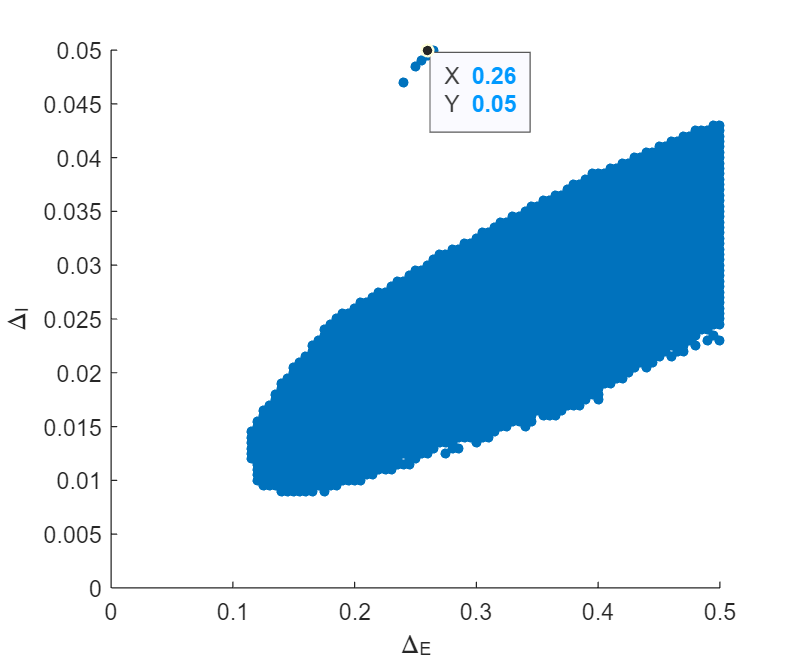

roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) == 1 && sum(gammaSheet(i,j,:)>0)==5 && sum(betaSheet(i,j,:)>0)==0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'filled',"MarkerFaceColor","#0072BD");
    hold on
end


% remove some points
roi(1,52:53) = 0; roi(2,52) = 0; roi(3,51) = 0; roi(4,50) = 0; roi(7,48) = 0;

xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
% legend([s1 s2],["Lateral agree","Lateral disagree"], ...
%     "Location","southeast");

x0 = 0; y0 = 0; width = 12; height = 10;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',10);
print('paraPlane', '-dpng', '-r600');
print('paraPlane', '-depsc', '-r600');